clear all
fn = 'D:\SPMDATAActive\Line Spectroscopy003.3ds'

fn = 'D:\SPMDATAActive\Line Spectroscopy003.3ds'

indList = -10:239

indList =    -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39


[header, data, par] = load3ds(fn,0)

header = 다음 필드를 포함한 struct :
                                                grid_dim: [240 1]
                                           grid_settings: [5×1 double]
                                                filetype: 'Linear'
                                            sweep_signal: 'Bias (V)'
                                        fixed_parameters: {'Sweep Start'  'Sweep End'}
                                   experiment_parameters: {'X (m)'  'Y (m)'  'Z (m)'  'Z offset (m)'  'Settling time (s)'  'Integration time (s)'  'Z-Ctrl hold'  'Final Z (m)'  'Scan:Current (A)'  'Scan:Input 7 (V)'  'Scan:Z (m)'}
                                          num_parameters: 13
                                         experiment_size: 2424
                                                  points: 101
                                                channels: {'Current (A)'  'Input 7 (V)'  'Bias (V)'  'Current [bwd] (A)'  'Input 7 [bwd] (V)'  'Bias [bwd] (V)'}
                                 

data =    -0.0000    0.5361   -0.4000   -0.0000    0.6298   -0.4000
   -0.0000    0.5359   -0.3920   -0.0000    0.5829   -0.3920
   -0.0000    0.5214   -0.3840   -0.0000    0.5563   -0.3840
   -0.0000    0.4956   -0.3760   -0.0000    0.5255   -0.3760
   -0.0000    0.4762   -0.3680   -0.0000    0.4915   -0.3680
   -0.0000    0.4506   -0.3600   -0.0000    0.4706   -0.3600
   -0.0000    0.4163   -0.3520   -0.0000    0.4541   -0.3520
   -0.0000    0.3735   -0.3440   -0.0000    0.4163   -0.3440
   -0.0000    0.3318   -0.3360   -0.0000    0.3997   -0.3360
   -0.0000    0.3643   -0.3280   -0.0000    0.3735   -0.3280


par =    -0.4000
    0.4000
   -0.0000
   -0.0000
   -0.0000
         0
    0.0001
    0.0500
    1.0000
       NaN


plot(data)
chan = header.channels

chan = 1×6 cell 배열
    {'Current (A)'}    {'Input 7 (V)'}    {'Bias (V)'}    {'Current [bwd] (A)'}    {'Input 7 [bwd] (V)'}    {'Bias [bwd] (V)'}


header.comment

ans = 'Across multiple domains in 1T-TaS2 after 0187.sxm'

numSwap =  header.grid_dim(1)

numSwap = 240

indx = 3

indx = 3

indy = [2,5]

indy =      2     5


V = data(:,indx)

V =    -0.4000
   -0.3920
   -0.3840
   -0.3760
   -0.3680
   -0.3600
   -0.3520
   -0.3440
   -0.3360
   -0.3280


y = data(:,indy)

y =     0.5361    0.6298
    0.5359    0.5829
    0.5214    0.5563
    0.4956    0.5255
    0.4762    0.4915
    0.4506    0.4706
    0.4163    0.4541
    0.3735    0.4163
    0.3318    0.3997
    0.3643    0.3735


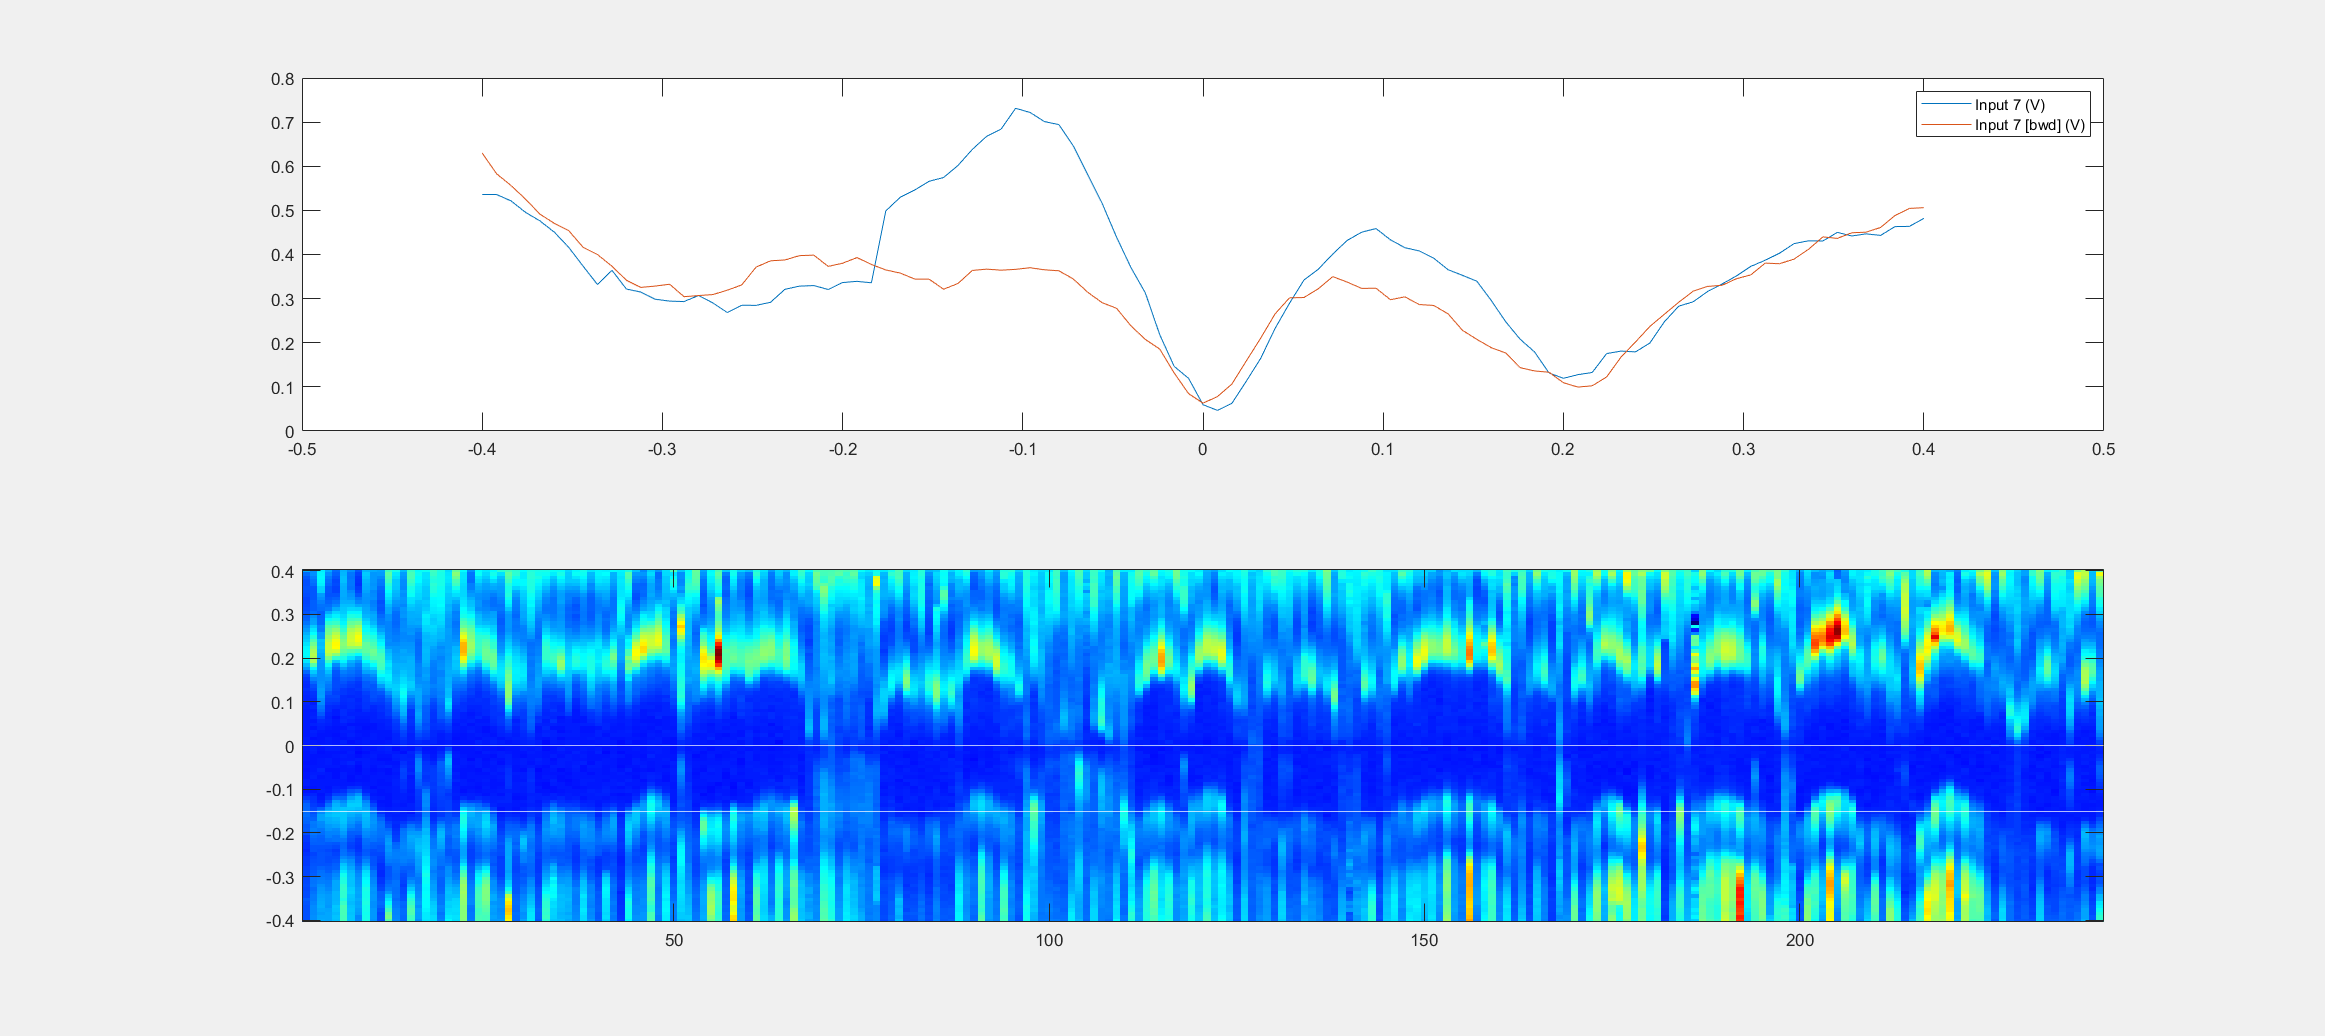

plot(V,y)
legend(chan(indy))

for ind = 1:numSwap
    [~, data] = load3ds(fn,ind-1);
    full(:,:,ind) = data(:,indy);
end
full = permute(full,[1,3,2]);
full = flip(full,1);

subplot(2,1,2)
imagesc(1:240,V([1 end]),full(:,:,1))
set(gca,'YDir','normal')
colormap(jet)
yline([0,-0.15],'w')
subplot(2,1,1)
plot(full(51,:,1))
xlim([0.5 100.5])
f = gcf()

f =   Figure (1) - 속성 있음:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [3421 200.2000 1860 828.8000]
       Units: 'pixels'

  모든 속성 표시


f.Visible ="on"

f =   Figure (1) - 속성 있음:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [3421 200.2000 1860 828.8000]
       Units: 'pixels'

  모든 속성 표시


pos = [3421	609	1860	420]

pos =         3421         609        1860         420


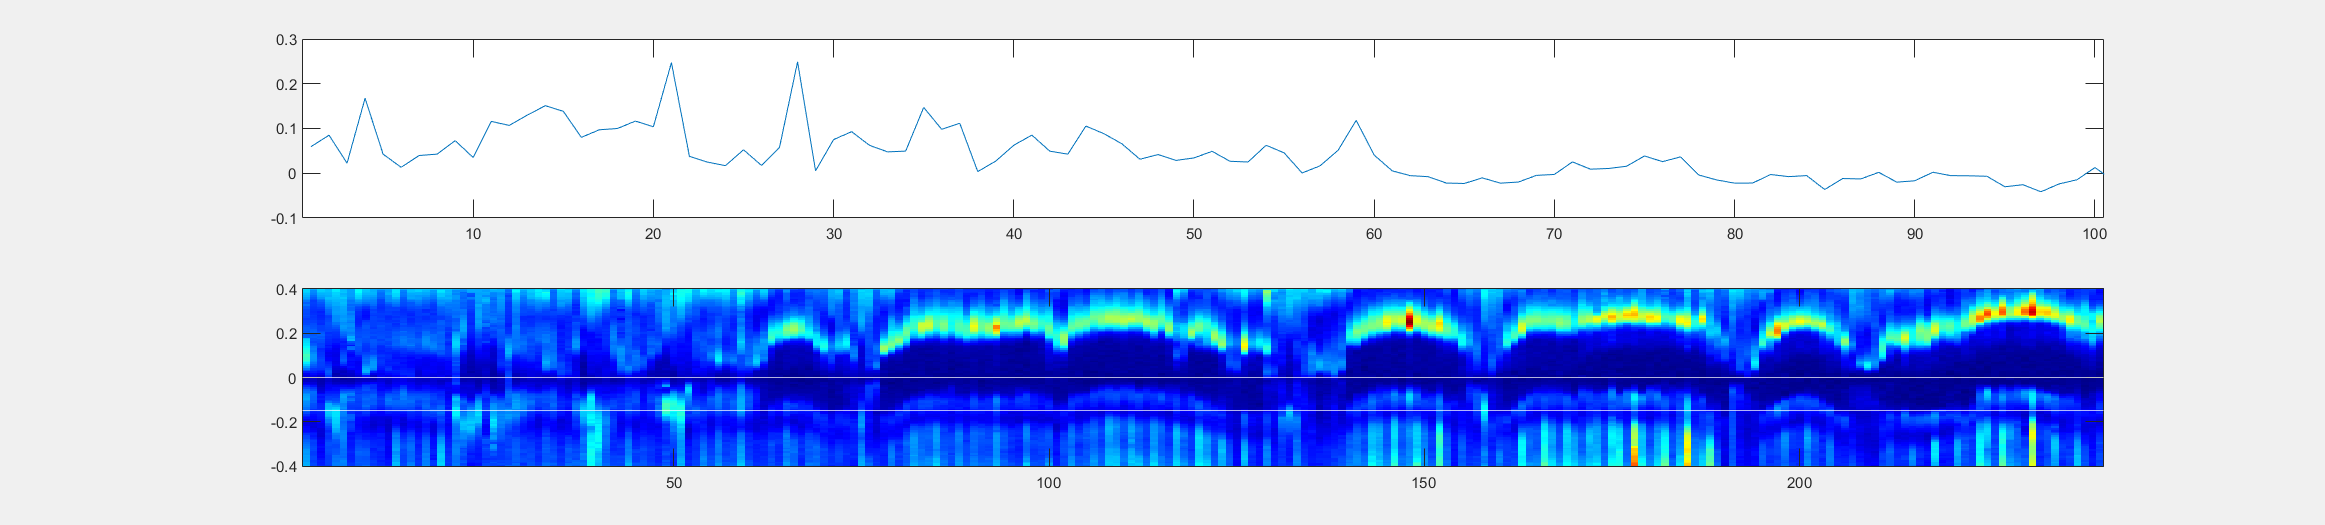

f =   Figure (1) - 속성 있음:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [3421 609 1860 420]
       Units: 'pixels'

  모든 속성 표시


f.Position = pos

header.experiment_parameters

ans = 1×11 cell 배열
    {'X (m)'}    {'Y (m)'}    {'Z (m)'}    {'Z offset (m)'}    {'Settling time (s)'}    {'Integration time (s)'}    {'Z-Ctrl hold'}    {'Final Z (m)'}    {'Scan:Current (A)'}    {'Scan:Input 7 (V)'}    {'Scan:Z (m)'}
